p1 = rand([3 1])*10;
k = rand([3 1]);
k = k/norm(k);
theta = rand*2*pi-pi

theta = -0.0919


p2 = rot(k,theta)*p1;

subproblem1(p1,p2,k)

ans = -0.0919

t = subproblem1_linear(p1,p2,k)

t = -0.0919

sp1_error(p1, p2, k, t)

ans = 2.6645e-15

p1 = rand([3 1])*rand*10;
k = rand([3 1]);
k = k/norm(k);
theta = rand*2*pi-pi

theta = 3.0143


%p2 = rot(k,theta)*p1;
p2 = rand([3 1])*rand*10;

t = subproblem1_linear(p1,p2,k)

t = -1.2588

sp1_error(p1, p2, k, t)

ans = 3.2590

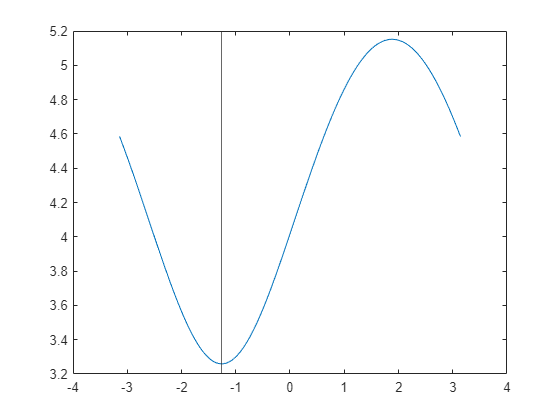


t_test = linspace(-pi, pi, 100);
e_test = NaN(size(t_test));
for i = 1:length(t_test)
    e_test(i) = sp1_error(p1, p2, k, t_test(i));
end

plot(t_test, e_test);
xline(t);

function e = sp1_error(p1, p2, k, theta)
    e = norm(p2 - rot(k, theta)*p1);
end